# **Nichelle Chung**

# **861093552**

# **Lab 2**

## **Part 1**

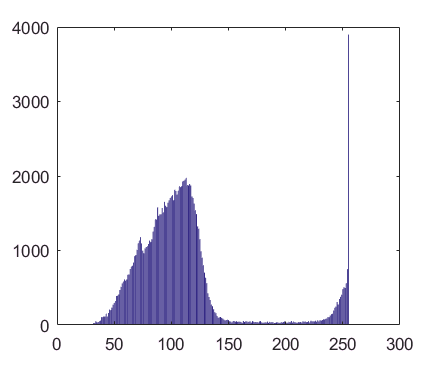

dots = imread('dots.png');
histArray = zeros(1,256);
x=0:1:255;
for i=1:size(dots,1)%300
    for j=1:size(dots,2)%400
        histArray(1,dots(i,j)) = histArray(1,dots(i,j))+1; 
    end
end
bar(histArray);

This histogram has the same max intensity as it should when the imhist function is called.

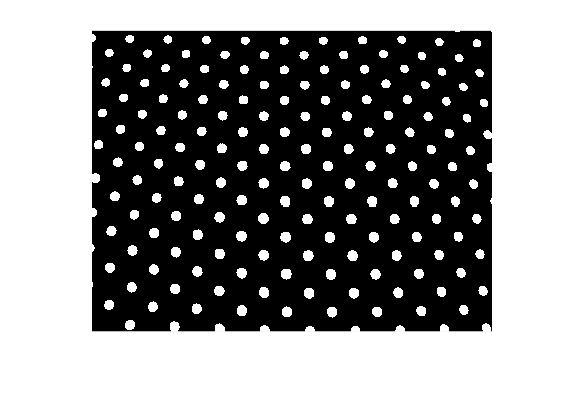

total = sum(histArray(:));
sum1 = dot((0:255), histArray);
wB = 0;
sumB = 0;
maximum = 0.0;
for x=1:256
    wB = wB + histArray(x);
    if(wB == 0)
        continue;
    end
    wF = total - wB;
    if(wF == 0)
        break;
    end
    sumB = sumB + (x-1) * histArray(x);
    mB = sumB / wB;
    mF = (sum1-sumB) / wF;
    between = wB * wF * (mB-mF) * (mB-mF);
    if(between >= maximum)
        level = x;
        maximum = between;
    end
end
threshold = level/256;
b1 = im2bw(dots,threshold);
imshow(b1);

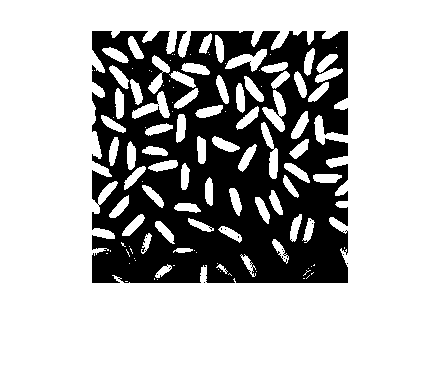

rice = imread('rice.png');
histArray = zeros(1,256);
x=0:1:255;
for i=1:size(rice,1)
    for j=1:size(rice,2)
        histArray(1,rice(i,j)) = histArray(1,rice(i,j))+1; 
    end
end
total = sum(histArray);
sum1 = dot((0:255), histArray);
wB = 0;
sumB = 0;
maximum = 0.0;
for x=1:256
    wB = wB + histArray(x);
    if(wB == 0)
        continue;
    end
    wF = total - wB;
    if(wF == 0)
        break;
    end
    sumB = sumB + (x-1) * histArray(x);
    mB = sumB / wB;
    mF = (sum1-sumB) / wF;
    between = wB * wF * (mB-mF) * (mB-mF);
    if(between >= maximum)
        level = x;
        maximum = between;
    end
end
threshold = level/256;
b1 = im2bw(rice,threshold);
imshow(b1);

The fact that the rice image lost some pixel from the grains of rice at the bottom can be due to the fact that the intensity varied more than the intensity of the dots image.

## **Part 2**

emask_1 = [1 0; 0 0];
emask_2 = [0 1; 0 0];
emask_3 = [0 0; 0 1];
emask_4 = [0 0; 1 0];
imask_1 = [1 1; 1 0];
imask_2 = [1 1; 0 1];
imask_3 = [0 1; 1 1];
imask_4 = [1 0; 1 1];
Ex = 0;
In = 0;
for i=1:299
    for j=1:399
        if (isequal(b1(i:i+1, j:j+1),emask_1)==1 || isequal(b1(i:i+1, j:j+1),emask_2)==1 || isequal(b1(i:i+1, j:j+1),emask_3)==1 || isequal(b1(i:i+1, j:j+1),emask_4)==1)
            Ex = Ex + 1;
        elseif (isequal(b1(i:i+1, j:j+1),imask_1)==1 || isequal(b1(i:i+1, j:j+1),imask_2)==1 || isequal(b1(i:i+1, j:j+1),imask_3)==1 || isequal(b1(i:i+1, j:j+1),imask_4)==1)
            In = In + 1;
        end
    end
end
(Ex-In)/4

ans = 170.2500

Although the actual count should be 180, by using the masking method taught in lecture this is the count it calculates. 

## Part 3

b2=b1;
label=bwlabel(b1);
onBorder=[];
for i=1:300
    for j=1:400
        if label(i,j)>0 && (i==1 || i==300 || j==1 || j==400)
            onBorder = [onBorder, label(i,j)];
        end
    end
end
for i=1:300
    for j=1:400
        if label(i,j)>0 && size(find(onBorder==label(i,j)),2)>0
            b2(i,j)=0;
        end
    end
end

Get rid of all dots that touch border, by identifying label of every dot touching border and setting every pixel corresponding to the label equal to 0.

countArea = zeros(1,161);
for i=1:300
    for j=1:400
        if label(i,j) > 0
            countArea(1,label(i,j)) = countArea(1,label(i,j)) + 1;
        end
    end
end
mean(countArea)

ans = 74.4037

Area of each dot calculated and average is taken.

label=bwlabel(b2);
findCenter = [];
pair  =[];
centroids = [];
for k=1:161
    findCenter = [];
    [row col] = find(label==k);
    findCenter = [row col];
    m = median(findCenter);
    centroids = [centroids; m];
end

Centroid found by finding the median of all points in dot. I have an array of 161 centroids, 1 for every grain of rice.

u_r = zeros(1,161);
u_c = zeros(1,161);
u_rc = zeros(1,161);
for r=1:300
    for c=1:400
        if(label(r,c) > 0)
            x = (r - centroids(label(r,c),1))^2;
            u_r(1,label(r,c)) = u_r(1,label(r,c)) + x;
            x = (c - centroids(label(r,c),2))^2;
            u_c(1,label(r,c)) = u_c(1,label(r,c)) + x;
            x = (r - centroids(label(r,c),1))*(c - centroids(label(r,c),2));
            u_rc(1,label(r,c)) = u_rc(1,label(r,c)) + x;
        end
    end
end
for k=1:161
    u_r(1,k) = u_r(1,k)/countArea(1,k);
    u_c(1,k) = u_c(1,k)/countArea(1,k);
    u_rc(1,k) = u_rc(1,k)/countArea(1,k);
end
mean(u_r)

ans = 6.0116

mean(u_c)

ans = 6.0154

mean(u_rc)

ans = 0.1363

Moments  of each dot calculated using formulas from class, averages are taken for all 3 moments.

## Part 4

rice_bin = imread('rice_binary.png');
label_rice=bwlabel(rice_bin,4);
countAreaRice = zeros(1,71);        %71 = number of rice grains
for i=1:256
    for j=1:256
        if label_rice(i,j) > 0
            countAreaRice(1,label_rice(i,j)) = countAreaRice(1,label_rice(i,j)) + 1;
        end
    end
end
maxAreaRice = find(countAreaRice==max(countAreaRice));

Max area found by adding up areas for each grain and storing in an array(countAreaRice)

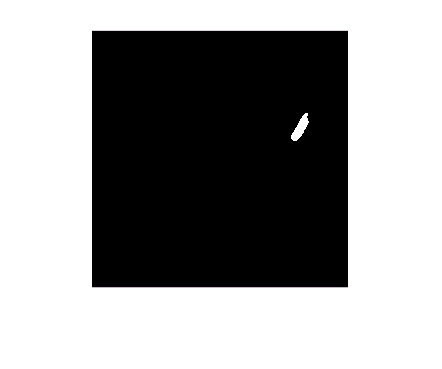

maxRice_bin = rice_bin;
for i=1:256
    for j=1:256
        if label_rice(i,j) ~= maxAreaRice
            maxRice_bin(i,j) = 0;
        else
            maxRice_bin(i,j) = 255;
        end
    end
end
imshow(maxRice_bin);

All pixels who's values arn't equal to the label of the max area rice are made equal to 0.

findCenter_rice = [];
pair =[];
centroids_rice = [];
for k=1:71
    findCenter_rice = [];
    [row col] = find(label_rice==k);
    findCenter_rice = [row col];
    m = median(findCenter_rice);
    centroids_rice = [centroids_rice; m];
end

Centroid found by finding the median of all points in grain. I have an array of 71 centroids, 1 for every grain of rice.


u_r_rice = zeros(1,71);
u_c_rice = zeros(1,71);
u_rc_rice = zeros(1,71);
for r=1:256
    for c=1:256
        if(label_rice(r,c) > 0)
            x = (r - centroids_rice(label_rice(r,c),1))^2;
            u_r_rice(1,label_rice(r,c)) = u_r_rice(1,label_rice(r,c)) + x;
            x = (c - centroids_rice(label_rice(r,c),2))^2;
            u_c_rice(1,label_rice(r,c)) = u_c_rice(1,label_rice(r,c)) + x;
            x = (r - centroids_rice(label_rice(r,c),1))*(c - centroids_rice(label_rice(r,c),2));
            u_rc_rice(1,label_rice(r,c)) = u_rc_rice(1,label_rice(r,c)) + x;
        end
    end
end
for k=1:71
    u_r_rice(1,k) = u_r_rice(1,k)/countAreaRice(1,k);
    u_c_rice(1,k) = u_c_rice(1,k)/countAreaRice(1,k);
    u_rc_rice(1,k) = u_rc_rice(1,k)/countAreaRice(1,k);
end
max_u_r_rice= find(u_r_rice==max(u_r_rice));
max_u_c_rice= find(u_c_rice==max(u_c_rice));
max_u_rc_rice= find(u_rc_rice==max(u_rc_rice));
min_u_r_rice = find(u_r_rice==min(u_r_rice));

Moments are calculated using formula given in class. Max of each moment is found.

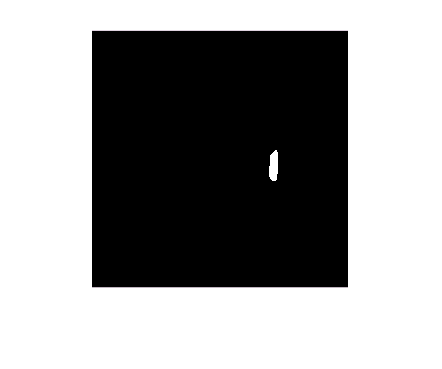

max_u_r_bin = rice_bin;
for i=1:256
    for j=1:256
        if label_rice(i,j) ~= max_u_r_rice
            max_u_r_bin(i,j) = 0;
        else
            max_u_r_bin(i,j) = 255;
        end
    end
end
imshow(max_u_r_bin);

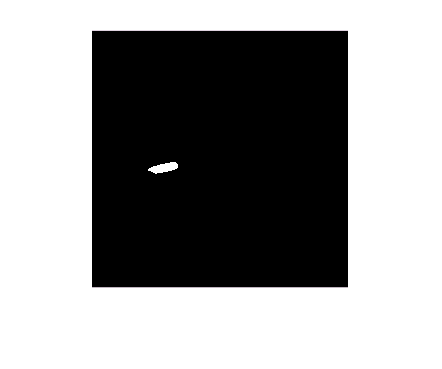

max_u_c_bin = rice_bin;
for i=1:256
    for j=1:256
        if label_rice(i,j) ~= max_u_c_rice
            max_u_c_bin(i,j) = 0;
        else
            max_u_c_bin(i,j) = 255;
        end
    end
end
imshow(max_u_c_bin);max_u_c_bin = rice_bin;

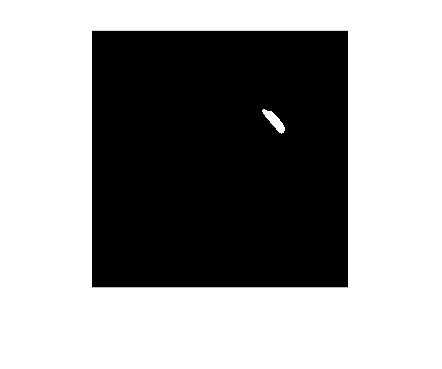

max_u_rc_bin = rice_bin;
for i=1:256
    for j=1:256
        if label_rice(i,j) ~= max_u_rc_rice
            max_u_rc_bin(i,j) = 0;
        else
            max_u_rc_bin(i,j) = 255;
        end
    end
end
imshow(max_u_rc_bin);

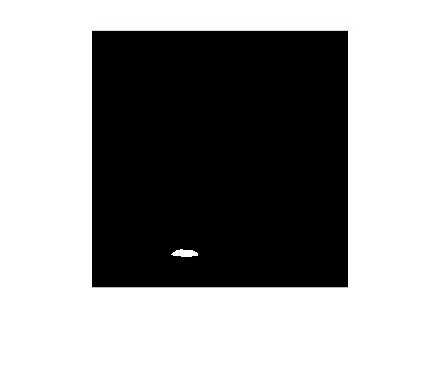

min_u_r_bin = rice_bin;
for i=1:256
    for j=1:256
        if label_rice(i,j) ~= min_u_r_rice
            min_u_r_bin(i,j) = 0;
        else
            min_u_r_bin(i,j) = 255;
        end
    end
end
imshow(min_u_r_bin);

The grain in #2 is vertical because the distance between the rows and the centroid is greater.

The grain in #3 is horizontal because the distance between the columns and the centroid is greater.

The grain in #4 is oriented diagonal because its at an angle and area at which the moment is greatest for the rows and columns.

The grain in #5 is oriented horizontal because the distance from the top of a horizontal grain to the center and the bottom of a horizontal grain to the center is small, and the area of this grain is also small.

## **Part 5**

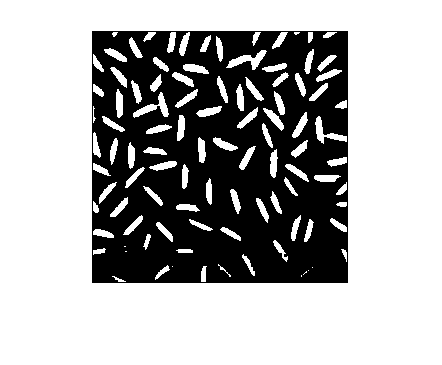

rice_thresh_bin = imread('rice_binary_manual_thresh.png');
bwmorph(rice_thresh_bin,'erode');

Erode: Erodes away most of the noise, but some of the grains of rice along with it.

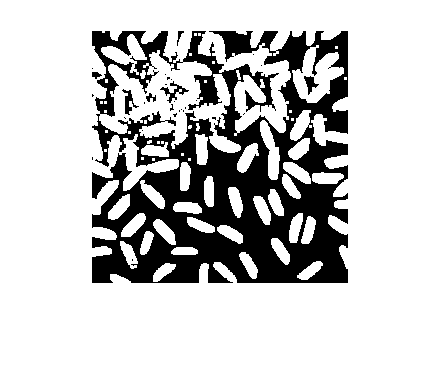

bwmorph(rice_thresh_bin,'dilate');

Dilate: Inflates the pixels which makes the rice appear smoother and filled in, but also inflates the noise pixels on the top left.

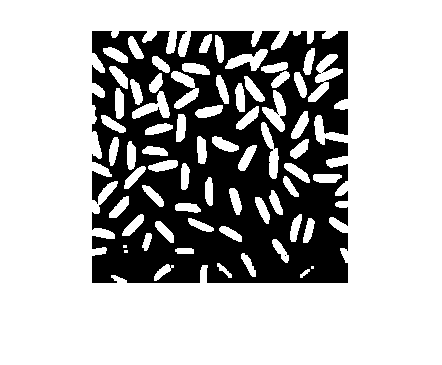

bwmorph(rice_thresh_bin,'open');

Open: First gets rid of grainyness and then smoothes, which results in a cleaner looking version of the first morphed image.

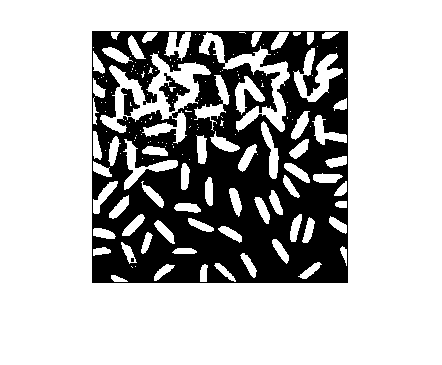

bwmorph(rice_thresh_bin,'close');

Close: First smoothes the pixels then inflates them, results in clear grains of rice but the noise at the top is still visible. 

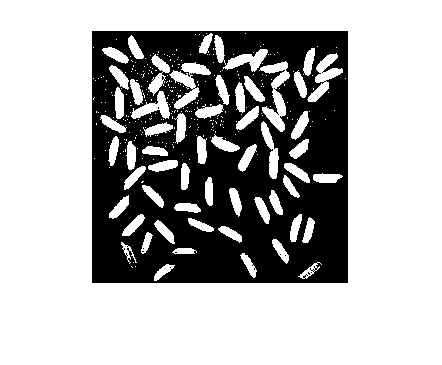

rice_thresh_bin2 = rice_thresh_bin;
label=bwlabel(rice_thresh_bin);
onBorder=[];
for i=1:size(rice_thresh_bin,1)
    for j=1:size(rice_thresh_bin,2)
        if label(i,j)>0 && (i==1 || i==size(rice_thresh_bin,1) || j==1 || j==size(rice_thresh_bin,2))
            onBorder = [onBorder, label(i,j)];
        end
    end
end
for i=1:size(rice_thresh_bin,1)
    for j=1:size(rice_thresh_bin,2)
        if label(i,j)>0 && size(find(onBorder==label(i,j)),2)>0
            rice_thresh_bin2(i,j)=0;
        end
    end
end
imshow(rice_thresh_bin2);

Rice grains on border removed.

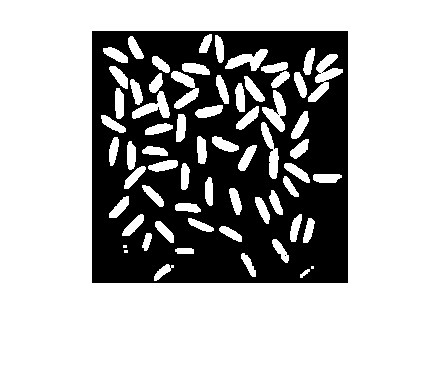

bwmorph(rice_thresh_bin2,'open');

After trying serveral combinations, performing the 'open' operation results in an outcome that looks most like rice_binary.png. When I apply other combinations some rice grains end up disappearing or clumping together with too many neighboring pieces. 